% path='\\sf3.bss.phy.private.cam.ac.uk\cicutagroup\yz655\modelling\circle_videos\paper_videos\wavelength\';
% filename='large_fx_0.1_fy_0.1_fxy_0_tauc_0_xc_0_yc_0_freq_0.3_gray.mp4';

path='\\sf3.bss.phy.private.cam.ac.uk\cicutagroup\yz655\modelling\circle_videos\paper_videos\direction\';
filename='large_theta_0.5236(rad)_fx_0.1_fy_0.173_fxy_0_tauc_0_xc_0_yc_0_freq_0.3_gray.mp4';

v = VideoReader([path filename]);

frame = zeros(v.Height,v.Width,v.Duration*v.FrameRate);
for i=1:v.NumFrames
    frame(:,:,i) = rgb2gray(readFrame(v));
end

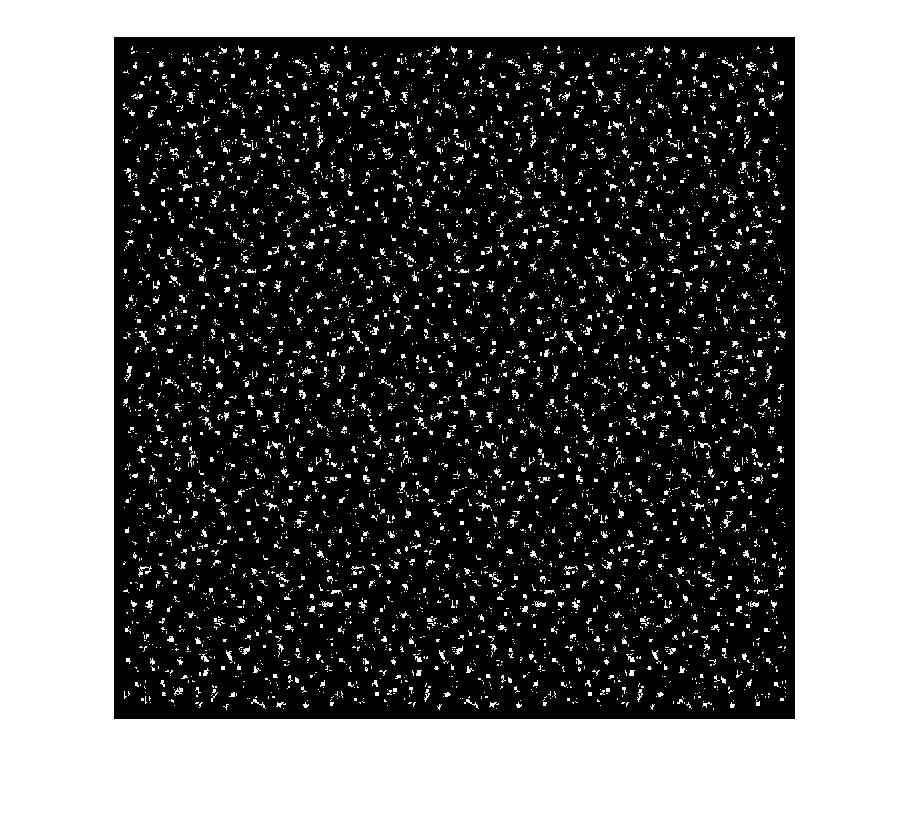

tau=16;
i=1;
imshow(frame(:,:,i)-frame(:,:,tau+i))

max_tau=v.Duration*v.FrameRate/2;
avg_diff_frame=zeros(v.Height,v.Width,max_tau);

tau=16;
N_couple_frames_to_average=100;
N_frames=100;
ind_frames = choose_ind_frames(tau, N_couple_frames_to_average, N_frames)

ind_frames =      3    19    35    51    67    83


%%%%%%%%%%%%%%%%
% calculate directly from pixel
%%%%%%%%%%%%%%%%

% clc
% clear

scale = 1024;
wheat_line_num = 31;
wheat_gap = scale/(wheat_line_num+1);
wheat_radius = wheat_gap*0.4;
f_x = 0.05; % 1/s
f_y = 0; % 1/s
tau_c = 10; % s
x_c = 500; %pixel
y_c = 500; %pixel

scale = 1024;
framerate = 10;
time = 10;
freq = double(0.3);  % Frequency in Hz, s^-1
f_xy = double(0);
ifTimeDecay = 0;
ifSpaceDecay = 0;
dot_size = 4;

theta_list=-pi:pi/6:pi;

theta=pi/6;
f_x = double(0.2*sin(theta)); % spatial frequency x-axis pixel^-1
f_y = double(0.2*cos(theta)); % spatial frequency y-axis pixel^-1

[phase_matrix,video_name] = make_phase_matrix(wheat_line_num, framerate,...
    time, freq, theta, f_x, f_y, f_xy, tau_c, x_c, y_c,...
    ifTimeDecay, ifSpaceDecay);
video_mat = make_video_pixel_matrix(phase_matrix, wheat_line_num, wheat_gap, wheat_radius, framerate,...
    time, scale, dot_size);
%     make_synthetic_video(video_mat, framerate, video_name, output_path);

save(video_name,"video_mat");

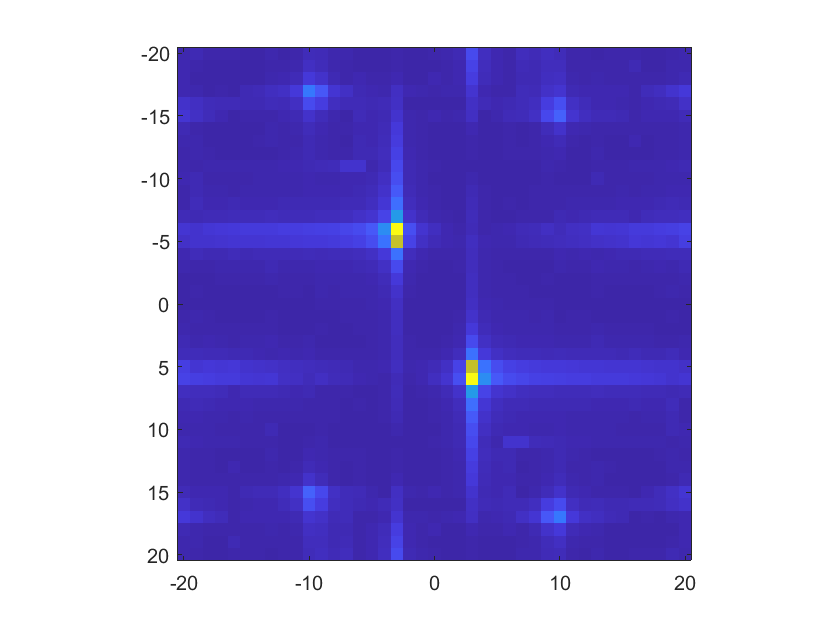

tau=16;
i=5;
% imshow()

diff=mat2gray(video_mat(:,:,i))-mat2gray(video_mat(:,:,tau+i));
% diff=video_mat(:,:,i)-video_mat(:,:,tau+i);
diff_fft=fftshift(fft2(diff));
diff_fft_abs=abs(fftshift(fft2(diff)));
scale=1024;
radius=scale/2+1;
q_range=20;
diff_fft_abs(radius,radius)=0;
imagesc(diff_fft_abs(radius-q_range:radius+q_range,radius-q_range:radius+q_range), 'XData', [-q_range q_range], 'YData', [-q_range q_range]);
set(gca,'dataAspectRatio',[1 1 1]);

%%%%%%%%%
%% Compare video read and video pixel matrix
%%%%%

video_diff=frame-video_mat;

% sum(video_diff,'all')
frame==video_mat

ans = 1024×1024×100 logical array
ans(:,:,1) =

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

make_synthetic_video(video_diff, framerate, 'diff', '')

make_synthetic_video(frame, framerate, 'frame', '')
make_synthetic_video(video_mat, framerate, 'video_mat', '')

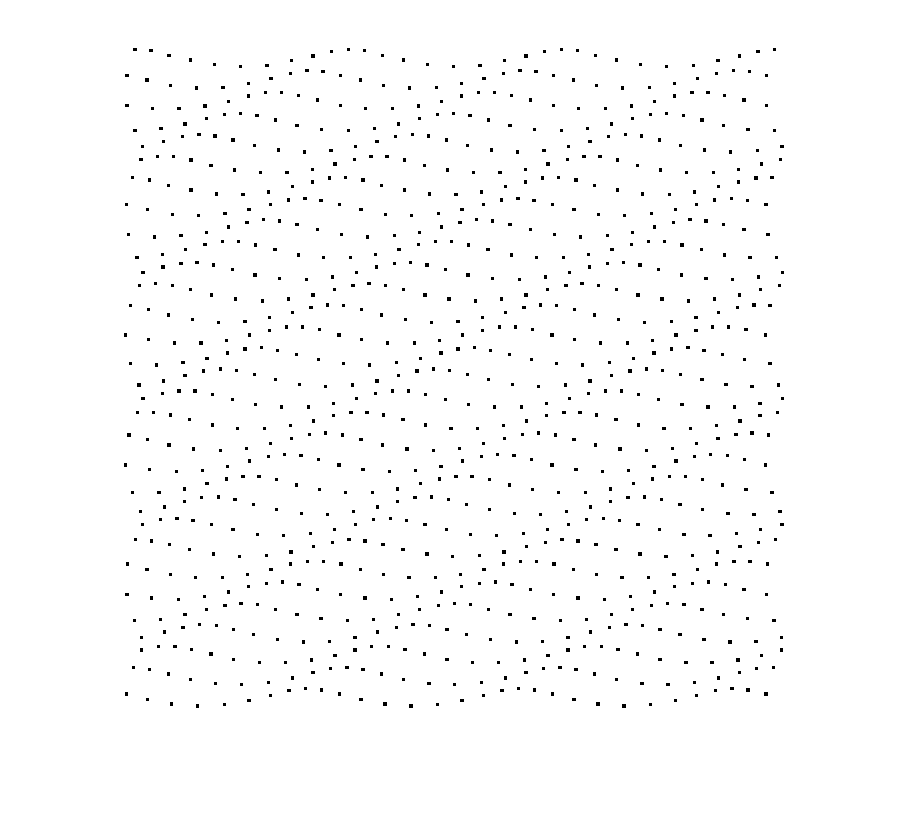

imshow(video_mat(:,:,i))

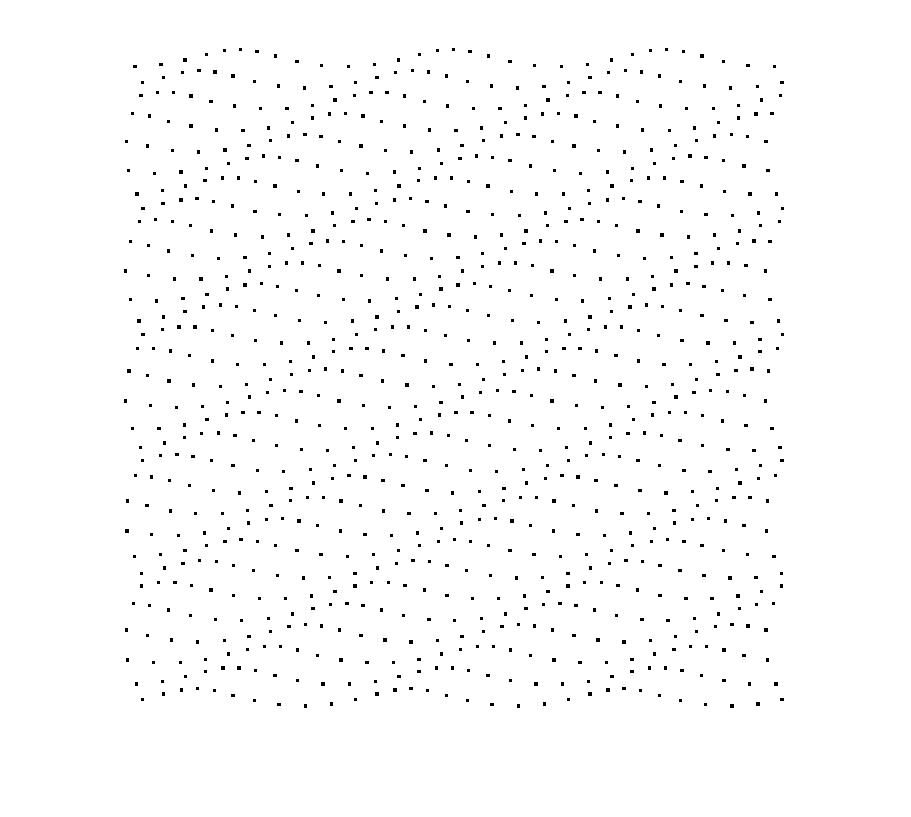

imshow(video_mat(:,:,tau+i))

xy = [1:wheat_line_num]*wheat_gap;
[X, Y] = meshgrid(xy);

function ind_frames = choose_ind_frames(tau, N_couple_frames_to_average, N_frames)
%choose_ind_frames returns the index of frames to use for subtracting

if isa(N_couple_frames_to_average,'char')
    
    ind_frames = 1:N_frames - tau;
    
else
    
    ind_frames_1 = randi(tau,1):tau:N_frames-tau;
    ind_frames_2 = randi(N_frames-tau,[1,N_couple_frames_to_average]);
    
    if numel(ind_frames_2)<numel(ind_frames_1)
        ind_frames = ind_frames_2;
    else
        ind_frames = ind_frames_1;
    end
    

end

end %function

function frame=plot_dot(frame,dot_x,dot_y,dot_size)
    half_dot_size=round(dot_size/2);
    frame(dot_y-half_dot_size:dot_y+half_dot_size,dot_x-half_dot_size:dot_x+half_dot_size)=0;
end

function [phase_matrix,video_name] = make_phase_matrix(wheat_line_num, framerate,...
    time, freq, theta, f_x, f_y, f_xy, tau_c, x_c, y_c,...
    ifTimeDecay, ifSpaceDecay)

    time_step = 1/framerate;
    frame_num = int8(time/time_step);
    frame_c = double(tau_c/time_step);
    phase_matrix = zeros([wheat_line_num,wheat_line_num,frame_num]);
    parfor t = 1:frame_num
        for j = 1:wheat_line_num
            for i = 1:wheat_line_num
                phase_matrix(i,j,t)=exp(-ifSpaceDecay*j/x_c-ifSpaceDecay*i/y_c-ifTimeDecay*double(t)/frame_c)*(2*pi*freq*time_step*double(t)-2*pi*f_x*j-2*pi*f_y*i+2*pi*f_xy*i*j);
            end    
        end
    end

    [x_c,y_c,tau_c] = deal(ifSpaceDecay*x_c,ifSpaceDecay*y_c, ifTimeDecay*tau_c);
    video_name = ['theta_' num2str(theta) '(rad)_fx_' num2str(f_x,3) '_fy_' num2str(f_y,3) ...
        '_fxy_' num2str(f_xy,5) '_tauc_' num2str(tau_c) ...
        '_xc_' num2str(x_c) '_yc_' num2str(y_c) '_freq_' ...
        num2str(freq) '_gray'];
end

function video_mat = make_video_pixel_matrix(phase_matrix, wheat_line_num, wheat_gap, wheat_radius, framerate,...
    time, scale, dot_size)

    time_step = 1/framerate;
    frame_num = int8(time/time_step);

    % make frame pixel matrix
    video_mat=ones(scale,scale,frame_num);
    
    for t=1:frame_num
        frame=255*ones(scale);
        current_phase_matrix=phase_matrix(:,:,t);
        x_offset = round(wheat_radius*cos(current_phase_matrix));
        y_offset = round(wheat_radius*sin(current_phase_matrix));
    
        for j = 1:wheat_line_num
            for i = 1:wheat_line_num
                dot_x=j*wheat_gap+x_offset(i,j);
                dot_y=i*wheat_gap+y_offset(i,j);
                frame=plot_dot(frame,dot_x,dot_y,dot_size);
            end
        end
        
        video_mat(:,:,t)=frame;
    end

end

function [] = make_synthetic_video(video_mat, framerate, video_name, output_path)
    output = [output_path 'large_' video_name];
    VidObj = VideoWriter(output, 'MPEG-4'); %set your file name and video compression
 
%     VidObj = VideoWriter('movie.avi', 'Uncompressed AVI'); %set your file name and video compression
    VidObj.FrameRate = 10; %set your frame rate
    open(VidObj);
    for f = 1:size(video_mat, 3)  
        writeVideo(VidObj,mat2gray(video_mat(:,:,f)));
    end
    close(VidObj);
end